# Recursive Least Square

## Practice 1: Estimate mass of vehicle

### Problem

There is an accelerating vehicle. This vehicle is a **two-wheel drive**, and the **diameter** of each wheel is **600 mm**.

If we can control the torque of the wheel, use the **input torque** and **measured acceleration** to determine the **mass of the vehicle**.

The torque is the value for one wheel.

(Assume that the torque is transferred to the ground without any errors or losses.)

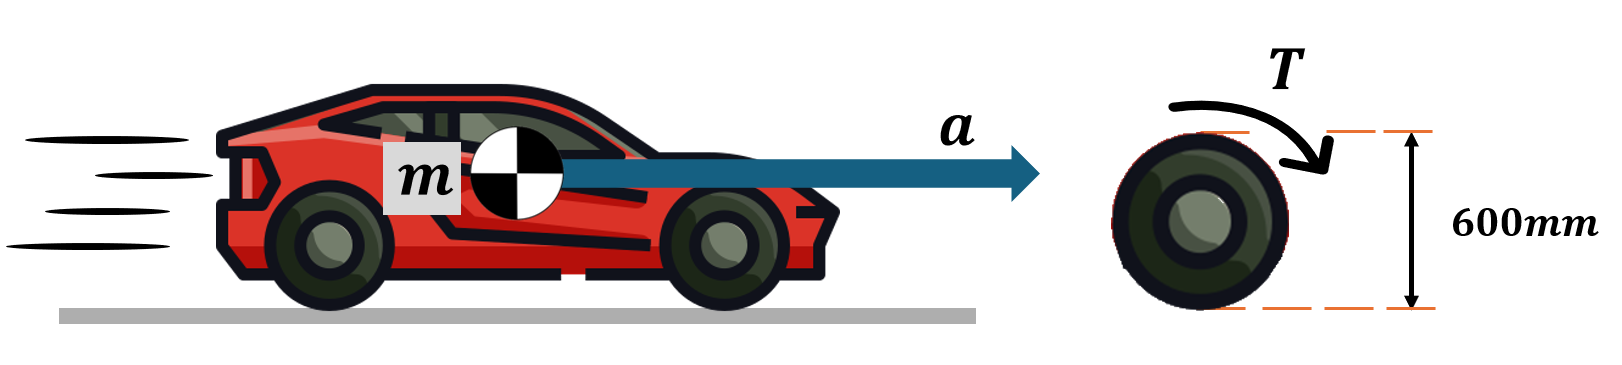

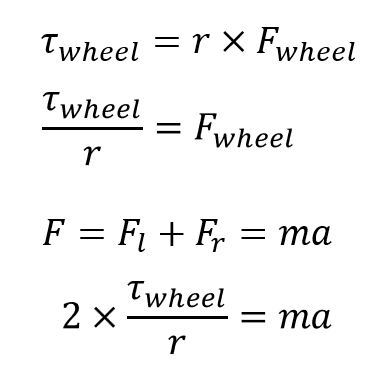

- τ_wheel : Wheel **torque**

- r : **Radius** of the wheel

- F_wheel : Wheel **force**

- F : **Total force** applied to the vehicle

- F_l : **Force** due to the **left wheel**

- F_r : **Force** due to the **right wheel**

- m : **Mass** of the vehicle

- a : **Acceleration** of the vehicle

### Measurement data

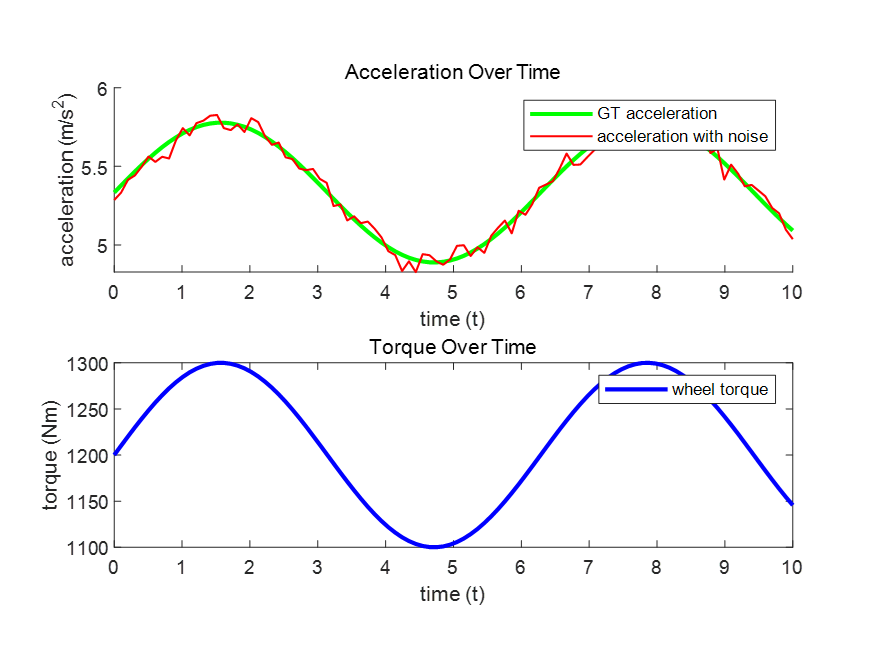

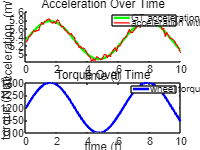

clear; close all;
load('least_square_mat_file_practice1.mat');
sim_total_steps = length(time);

figure;
subplot(2,1,1);
hold on;
plot(time, gt_accelerations_mps2, 'g-', 'LineWidth', 2);
plot(time, accelerations_with_noise_mps2, 'r-', 'LineWidth', 1);
xlabel('time (t)');
ylabel('acceleration (m/s^2)');
legend('GT acceleration', 'acceleration with noise');
title('Acceleration Over Time');

subplot(2,1,2);
plot(time, torques_Nm, 'b-', 'LineWidth', 2);
xlabel('time (t)');
ylabel('torque (Nm)');
legend('wheel torque');
title('Torque Over Time');
hold off;

### Recursive least square modeling

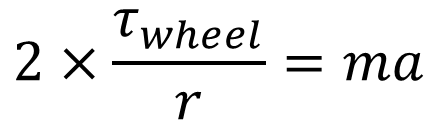

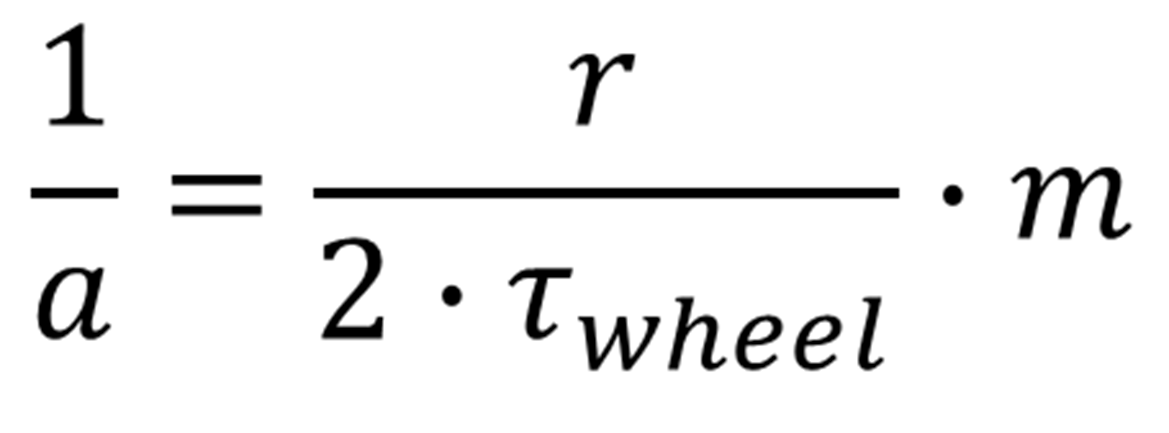

#### Least square modeling

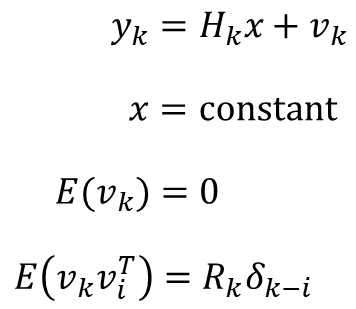

- 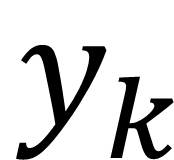: measurement vector

- 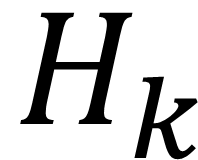: measurement matrix

- 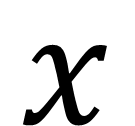: state vector

#### Initialization

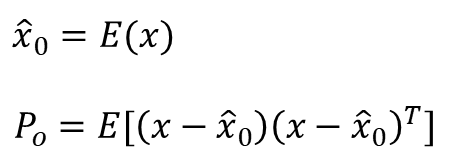

- 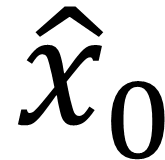: Initial estimated state vector

- 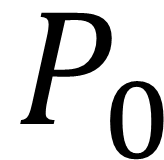: Initial estimation-error covariance

#### Recursive estimation

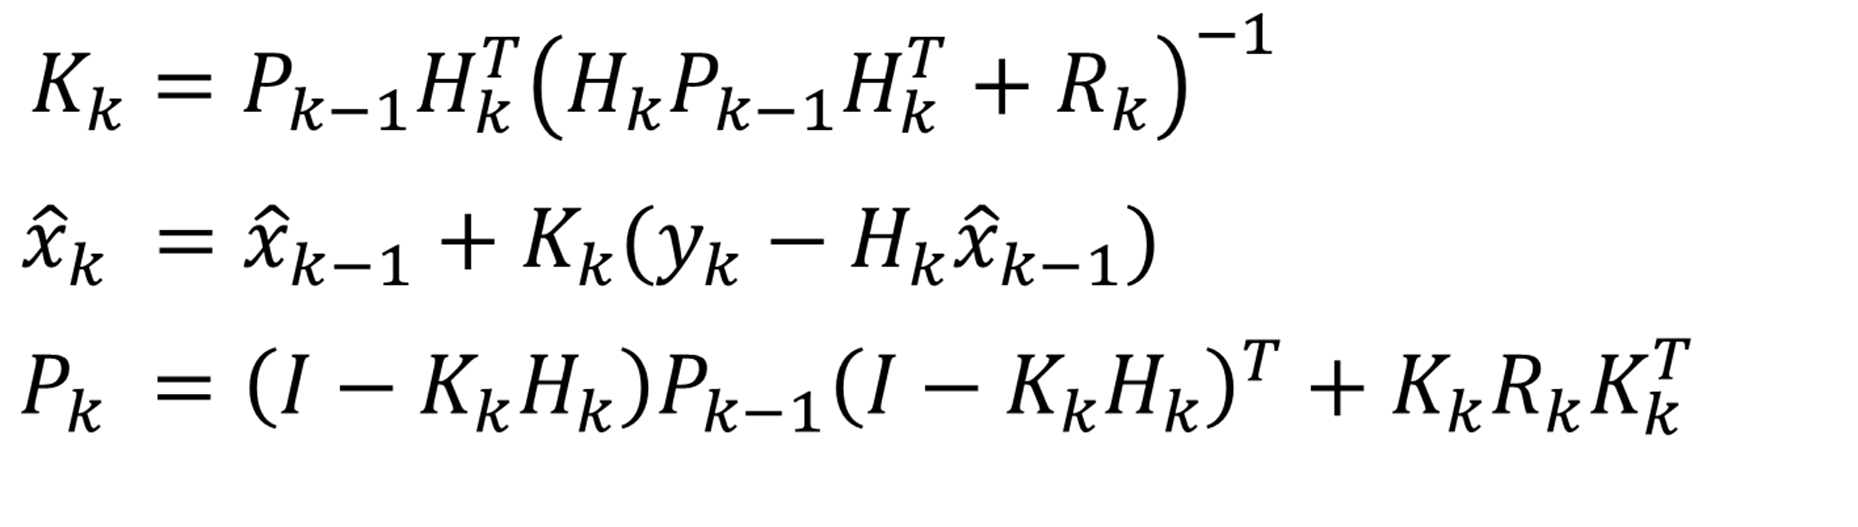

- 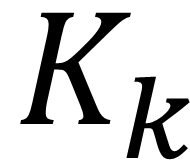: estimator gain matrix

- 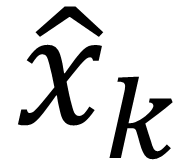: estimated state vector

- 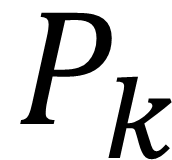: estimation-error covariance

Num_of_state = 1; % mass_kg
Num_of_measurement_order = 1; % acceleration
H = zeros(sim_total_steps, Num_of_state);
Y = zeros(sim_total_steps, Num_of_measurement_order);

x_rls = zeros(Num_of_state, sim_total_steps);
P_rls = cell(sim_total_steps,1);

% Initialize
x0 = 1000;
P0 = 1e+10;

% ToDo: Determine measurement covariance matrix R
R = 0.01^2;    % example

isFirstStep = true;
for idxSim = 1: sim_total_steps
    if isFirstStep == true
        prev_x = x0;
        prev_p = P0;
        isFirstStep = false;
    else
        prev_x = x_rls(:, idxSim-1);
        prev_p = P_rls{idxSim-1};
    end

    %%%% TODO %%%%
    % Modeling H_k matrix
    H(idxSim,:) = wheel_radius_m/(2*torques_Nm(idxSim,:)) ;

    % Determine gain K_k
    K = prev_p*(H(idxSim,:)')*inv(H(idxSim,:)*prev_p*(H(idxSim,:)')+R) ;

    % Define the measurement y_k
    y_k(:,idxSim) = 1/accelerations_with_noise_mps2(idxSim,:);

    % Update estimating state \hat(x)_k
    x_rls(:,idxSim) = prev_x + K*(y_k(:,idxSim)-H(idxSim,:)*prev_x) ;

    % Update uncertainty P_k
    P_rls{idxSim} = (eye(Num_of_state)-K*H(idxSim,:))*prev_p*(eye(Num_of_state)-K*H(idxSim,:))'+K*R*(K.');
end

%%%% TODO %%%%
estimated_mass = x_rls(:, sim_total_steps);

% Estimated result
fprintf('Estimated mass: %.2f kg\n', estimated_mass);

Estimated mass: 1500.35 kg


fprintf('GT mass: %.2f kg\n', gt_mass_kg);

GT mass: 1500.00 kg


### Visualize Result

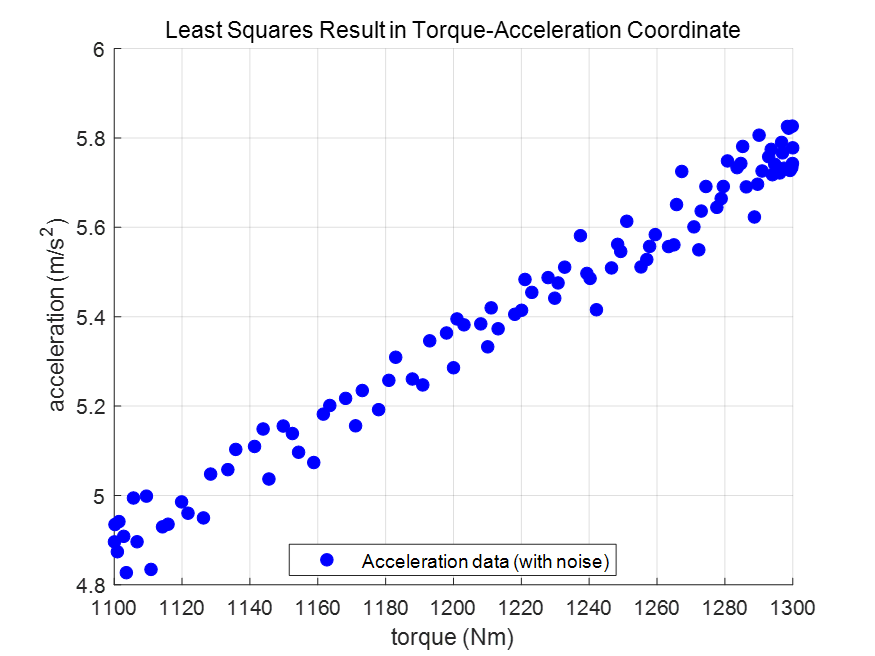

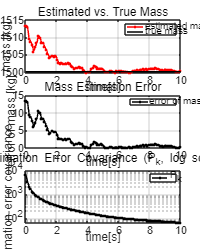

error_rls = abs(x_rls - gt_mass_kg);

figure('Name','[Practice 1: State and Covariance]','Position',[100,100,800,1000]);
subplot(3,1,1)
plot(time, x_rls(1,:), 'r.-');
hold on;
plot(time, gt_mass_kg * ones(sim_total_steps,1),'k');
legend('estimated mass','true mass'); 
title('Estimated vs. True Mass');
xlabel('time[s]');
ylabel('mass [kg]');
grid on; hold off;

subplot(3,1,2)
plot(time, error_rls(1,:), 'k.-');
legend('error of mass'); 
title('Mass Estimation Error');
xlabel('time[s]');
ylabel('error of mass [kg]');
grid on;

subplot(3,1,3)
P_rls_mat = cell2mat(P_rls)';
semilogy(time, P_rls_mat(1,:), 'k.-');
legend('P_k'); 
title('Estimation Error Covariance (P_k, log scale)');
xlabel('time[s]');
ylabel('estimation-error covariance');
grid on;

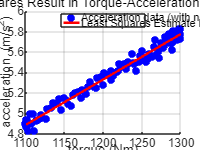



figure;
hold on;
plot(torques_Nm, accelerations_with_noise_mps2, 'bo', 'MarkerFaceColor', 'b');
torques_line = linspace(min(torques_Nm), max(torques_Nm), 100);
accelerations_line = (2 * torques_line / wheel_radius_m) / estimated_mass;
plot(torques_line, accelerations_line, 'r-', 'LineWidth', 2);
xlabel('torque (Nm)');
ylabel('acceleration (m/s^2)');
title('Least Squares Result in Torque-Acceleration Coordinate');
legend('Acceleration data (with noise)', 'Least Squares Estimate Line', 'Location', 'best');
grid on;
hold off;

## Practice 2: Estimate initial position, velocity, and acceleration

### Problem

There is a **free-falling object**.

The **range sensor** can measure the **altitude of a free-falling object**.

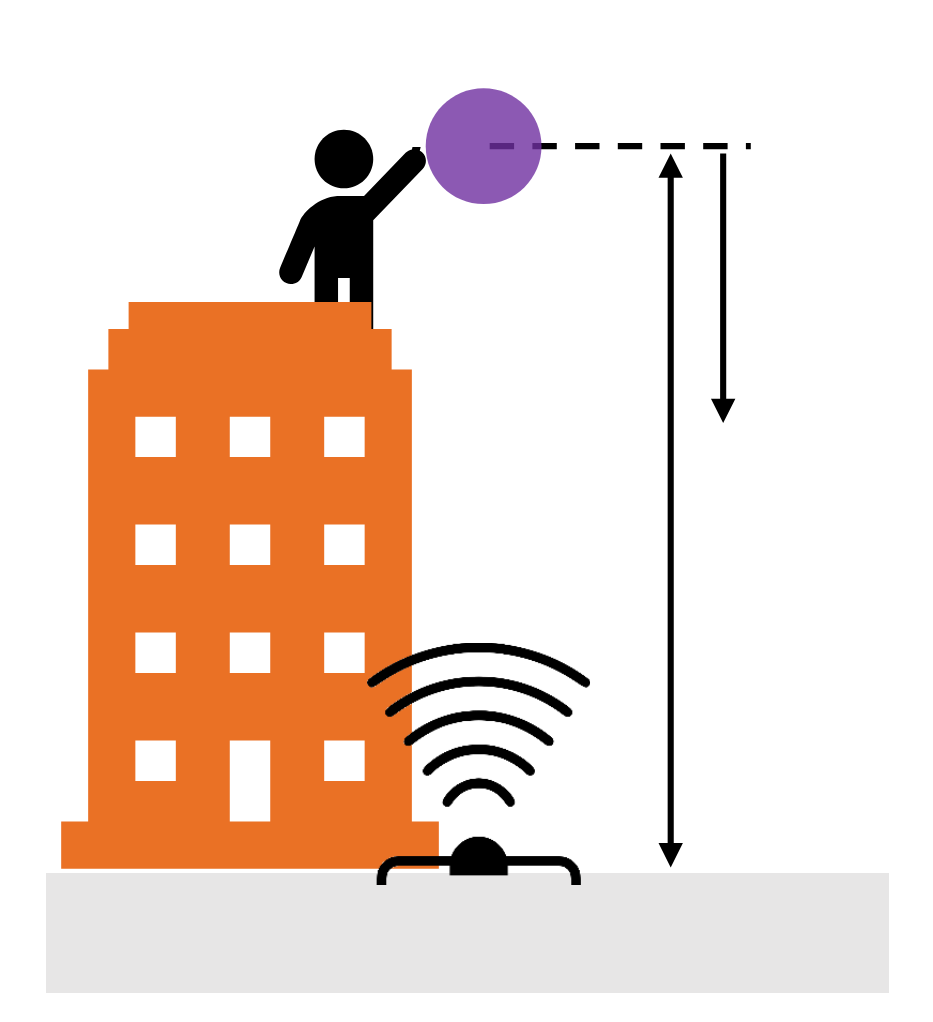

A discrete model of the free-falling object can be represented as follow: 

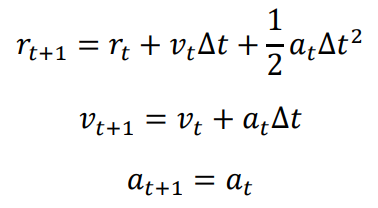

The discrete state space description of this system can be written as follow:

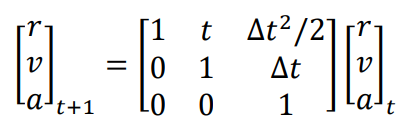

We have the sampling time and initial information as below:

1) ∆𝑡 = 0.1

2) gravitational acceleration (𝑎 = 𝑔 = −9.80665 𝑚/𝑠^2 ) model

3) initial velocity 𝑣_0 = 2.5 𝑚/𝑠

4) initial range 𝑟_0 = 100 𝑚

### GroundTruth data

Plot the simulation (x-axis is time and y-axes are r_t, v_t, and a_t.

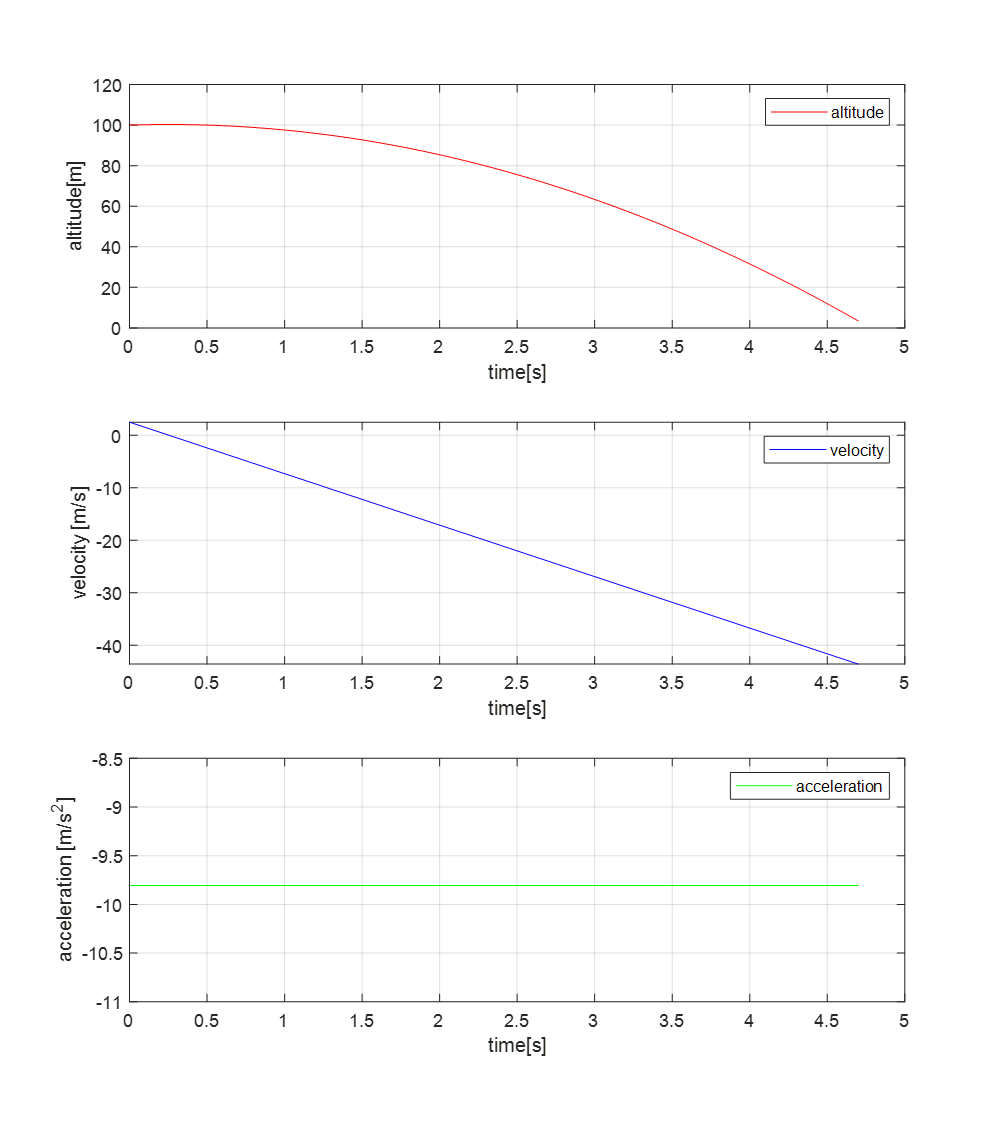

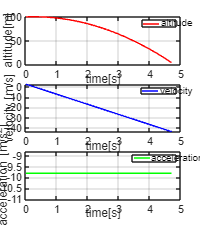

clear; close all;
load('least_square_mat_file_practice2.mat');

% Plot
figure('Name','Practice 2: Simulation data generation','Position',[100,100,840,945]);
subplot(3,1,1)
plot(sim_time, sim_altitude, 'r');
legend('altitude');
xlabel('time[s]');
ylabel('altitude[m]');
grid on;

subplot(3,1,2)
plot(sim_time, sim_velocity, 'b');
legend('velocity');
xlabel('time[s]');
ylabel('velocity [m/s]');
grid on;

subplot(3,1,3)
plot(sim_time, sim_acceleration, 'g');
legend('acceleration');
xlabel('time[s]');
ylabel('acceleration [m/s^2]');
grid on;

### Measurement data with noise

The **noise distribution** of this sensor is normally distributed.

The '**Actual range [m]**' as the** mean (μ)** and 

'**Actual range * 0.1 [m]**' as the** standard deviation (σ)**.

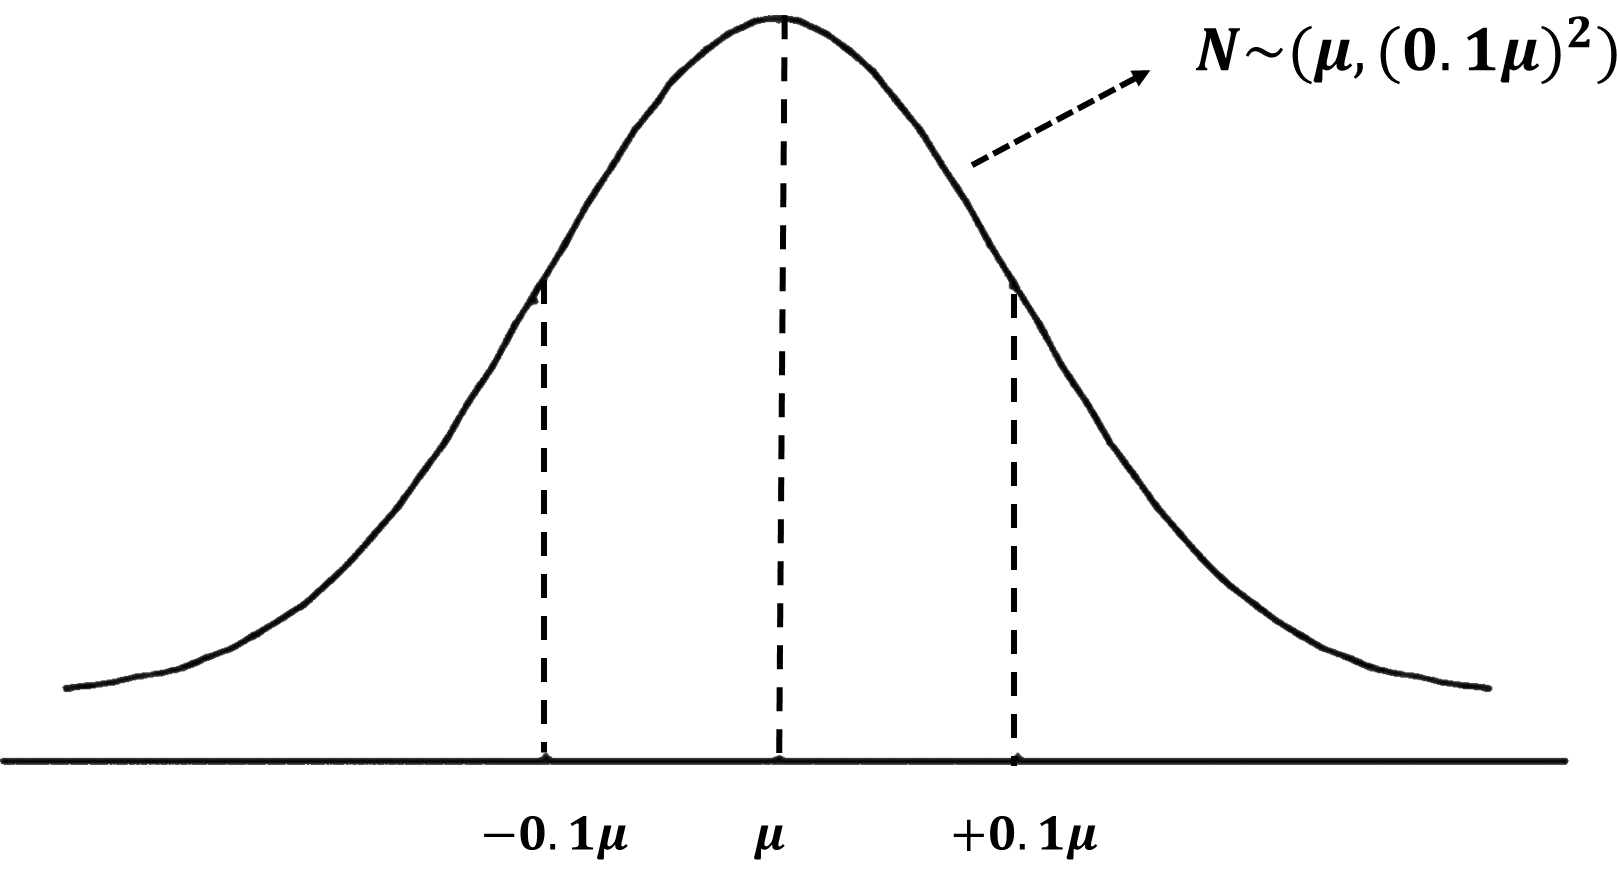

- μ : **Actual range** [m] -- **Mean** of the noise distribution

- σ : **Actual range * 0.1** [m] -- **Standard deviation** of the noise distribution

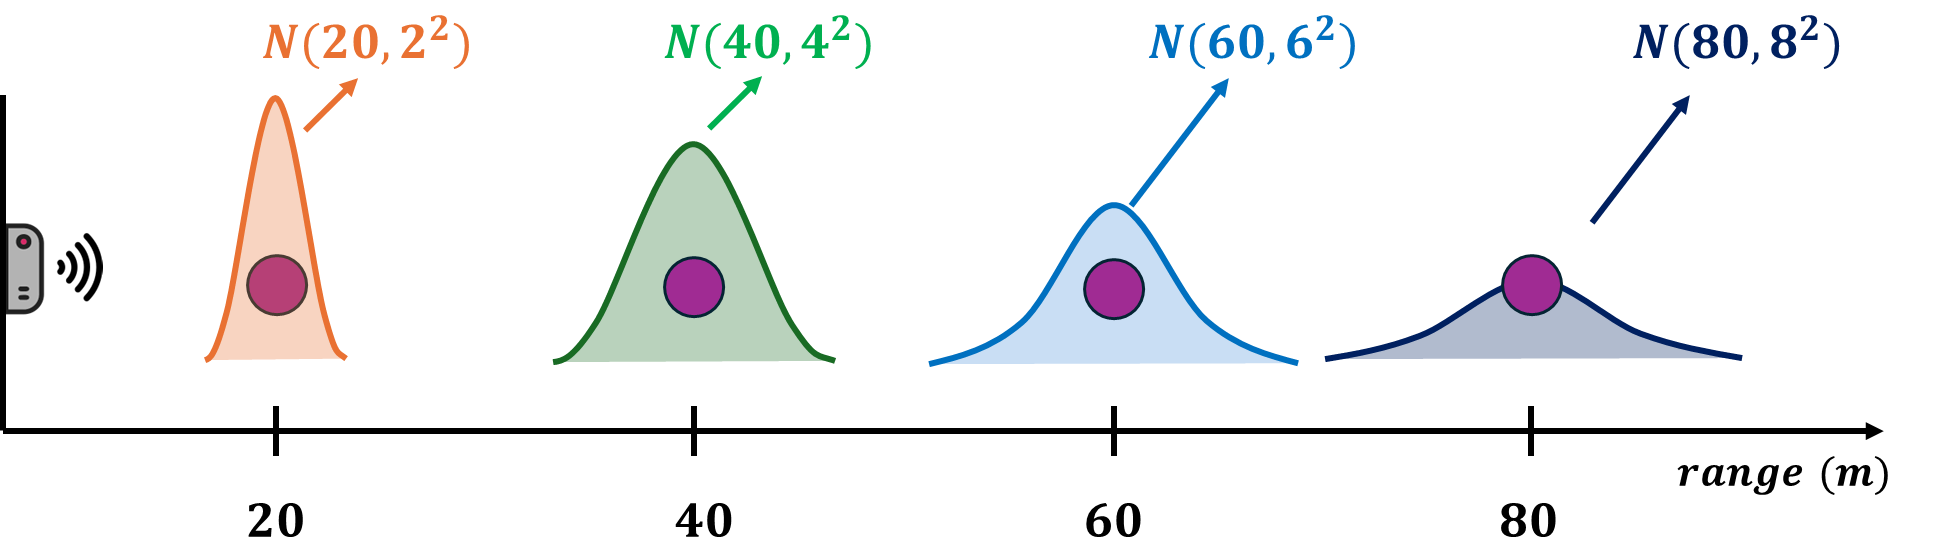

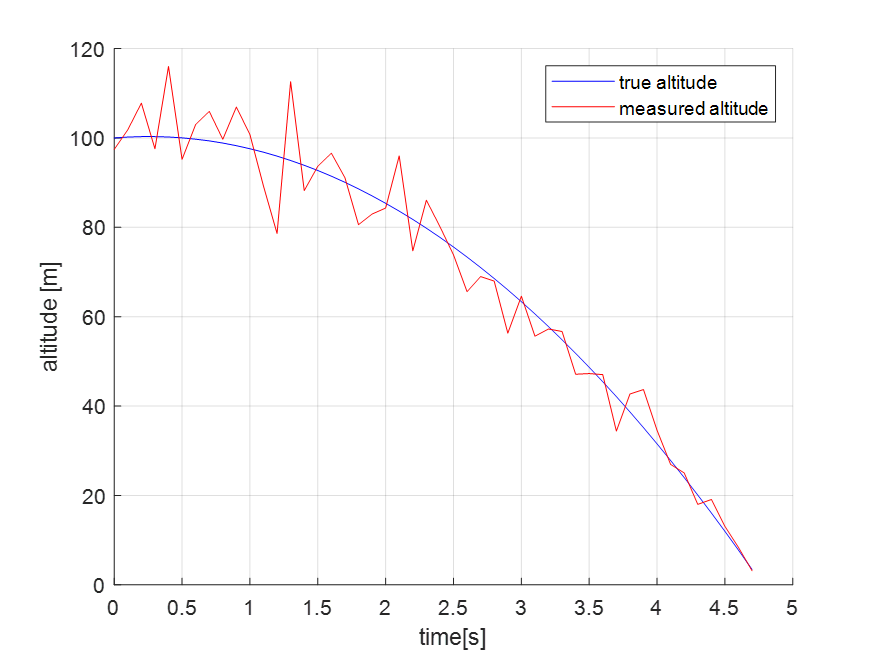

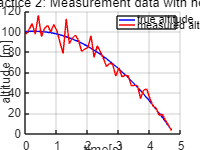

% Plot
figure('Name','Practice 2: Measurement data with noise');
hold on;
plot(sim_time, sim_altitude, 'b');
plot(sim_time, sim_altitude_sensor, 'r');
legend('true altitude', 'measured altitude'); xlabel('time[s]'); ylabel('altitude [m]'); grid on;
title("Practice 2: Measurement data with noise")
hold off;

### Least square modeling

Find the r0, v0, and a0 using simulation data through least square estimation.

A discrete model of the free-falling object can be represented as follow: 

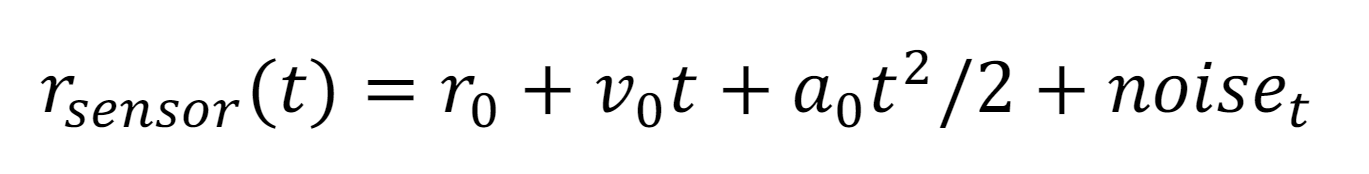

The discrete state space description of this system can be written as follow:

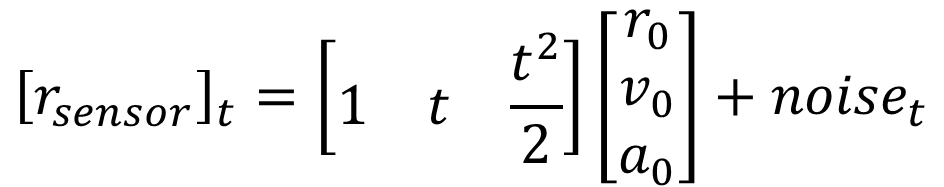

#### Least square modeling

- : measurement vector

- : measurement matrix

- : state vector

#### Initialization

- : Initial estimated state vector

- : Initial estimation-error covariance

#### Recursive estimation

- : estimator gain matrix

- : estimated state vector

- : estimation-error covariance

Num_of_state = 3; % r0, v0, a0
Num_of_measurement_order = 1; % height
H = zeros(sim_total_steps, Num_of_state);
Y = zeros(sim_total_steps, 1);

x_rls = zeros(Num_of_state, sim_total_steps);
P_rls = cell(sim_total_steps,1);
R = zeros(Num_of_measurement_order, sim_total_steps);

% Initialize
P0 = [10e10  0   0;
       0  10e10  0;
       0   0  10e10];
x0 = [0 0 0]';

isFirstStep = true;
for idxSim = 1: sim_total_steps
    if isFirstStep == true
        prev_x = x0;
        prev_p = P0;
        isFirstStep = false;
    else
        prev_x = x_rls(:,idxSim-1);
        prev_p = P_rls{idxSim-1};
    end
    %%%% TODO %%%%
    % Modeling H_k matrix
    H(idxSim,:) = [1, sim_time(idxSim), sim_time(idxSim).^2/2] ;

    % ToDo: Determine measurement uncertainty R_k, ('Actual range * 0.1 [m]')
    R(1,idxSim) = (sim_altitude_sensor(idxSim,:)*0.1)^2 ;

    % Determine gain K_k
    K = prev_p*H(idxSim,:)'*(H(idxSim,:)*prev_p*H(idxSim,:)'+R(idxSim))^(-1);

    % Define the measurement y_k
    Y(idxSim,1) = sim_altitude_sensor(idxSim,:) ;

    % Update estimating state \hat(x)_k
    x_rls(:,idxSim) = prev_x+K*(Y(idxSim,1)-H(idxSim,:)*prev_x) ;

    % Update uncertainty P_k
    P_rls{idxSim} = (eye(Num_of_state)-K*H(idxSim,:))*prev_p*(eye(Num_of_state)-K*H(idxSim,:))'+K*R(1,idxSim)*K';

end

estimated_x_rls = x_rls(:, sim_total_steps);
sim_true = [init_altitude; init_velocity; init_acceleration];
estimated_error_rls = abs(estimated_x_rls - sim_true);

fprintf('Least Square result   \n');

Least Square result   


fprintf('Estimated r0: %f, v0: %f, a0: %f   \n', estimated_x_rls(1), estimated_x_rls(2), estimated_x_rls(3));

Estimated r0: 100.448251, v0: 1.504383, a0: -9.429629   


fprintf('GT r0: %f, v0: %f, a0: %f   \n', sim_true(1), sim_true(2), sim_true(3));

GT r0: 100.000000, v0: 2.500000, a0: -9.806650   


fprintf('r0_error: %f, v0_error: %f, a0_error: %f   \n', estimated_error_rls(1), estimated_error_rls(2), estimated_error_rls(3));

r0_error: 0.448251, v0_error: 0.995617, a0_error: 0.377021   


#### **Visualization**

error_rls = abs(x_rls - sim_true);
P_rls_mat = cell2mat(P_rls);

P_rls_3d = zeros(3, 3, sim_total_steps);
for k = 1:sim_total_steps
    P_rls_3d(:,:,k) = P_rls{k};
end

P_11 = squeeze(P_rls_3d(1,1,:));
P_22 = squeeze(P_rls_3d(2,2,:));
P_33 = squeeze(P_rls_3d(3,3,:));

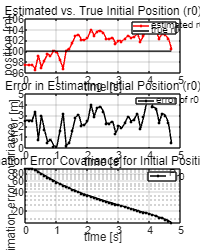

%% Plot for r0 (initial position)
figure('Name','[Practice 2: State and Covariance]','Position',[100,100,800,1000]);

subplot(3,1,1)
plot(sim_time, x_rls(1,:), 'r.-');
hold on;
plot(sim_time, sim_true(1) * ones(sim_total_steps,1),'k');
legend('estimated r0','true r0'); 
xlabel('time [s]');
ylabel('position [m]');
title('Estimated vs. True Initial Position (r0)');
grid on; hold off;

subplot(3,1,2)
plot(sim_time, error_rls(1,:), 'k.-');
legend('error of r0'); 
xlabel('time [s]');
ylabel('error [m]');
title('Error in Estimating Initial Position (r0)');
grid on;

subplot(3,1,3)
semilogy(sim_time, P_11, 'k.-');
legend('P_{r0}'); 
xlabel('time [s]');
ylabel('estimation-error covariance');
title('Estimation Error Covariance for Initial Position (r0)');
grid on;

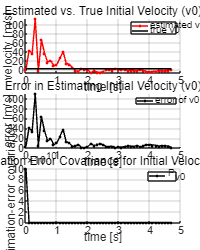

%% Plot for v0 (initial velocity)
figure('Name','[Practice 2: State and Covariance - v0]','Position',[100,100,800,1000]);

subplot(3,1,1)
hold on;
plot(sim_time, x_rls(2,:), 'r.-');
plot(sim_time, sim_true(2) * ones(sim_total_steps,1),'k');
legend('estimated v0','true v0'); 
xlabel('time [s]'); ylabel('velocity [m/s]');
title('Estimated vs. True Initial Velocity (v0)');
grid on; hold off;

subplot(3,1,2)
hold on;
plot(sim_time, error_rls(2,:), 'k.-');
legend('error of v0'); 
xlabel('time [s]'); ylabel('error [m/s]');
title('Error in Estimating Initial Velocity (v0)');
grid on; hold off;

subplot(3,1,3)
hold on;
plot(sim_time, P_22, 'k.-');
legend('P_{v0}'); 
xlabel('time [s]'); ylabel('estimation-error covariance');
title('Estimation Error Covariance for Initial Velocity (v0)');
grid on; hold off;

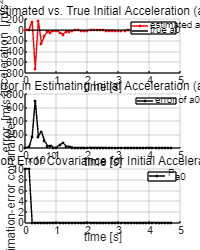

%% Plot for a0 (initial acceleration)
figure('Name','[Practice 2: State and Covariance - a0]','Position',[100,100,800,1000]);

subplot(3,1,1)
hold on;
plot(sim_time, x_rls(3,:), 'r.-');
plot(sim_time, sim_true(3) * ones(sim_total_steps,1),'k');
legend('estimated a0','true a0'); 
xlabel('time [s]'); ylabel('acceleration [m/s^2]');
title('Estimated vs. True Initial Acceleration (a0)');
grid on; hold off;

subplot(3,1,2)
hold on;
plot(sim_time, error_rls(3,:), 'k.-');
legend('error of a0'); 
xlabel('time [s]'); ylabel('error [m/s^2]');
title('Error in Estimating Initial Acceleration (a0)');
grid on; hold off;

subplot(3,1,3)
hold on;
plot(sim_time, P_33, 'k.-');
legend('P_{a0}'); 
xlabel('time [s]'); ylabel('estimation-error covariance');
title('Estimation Error Covariance for Initial Acceleration (a0)');
grid on; hold off;